clear all
clc
close all

% YALMIP code to solve a simple LMI optimization problem

% Define constants
k = 20;          % known constant in the inequality x < -k/y
y_min = 0.1;    % lower bound on y
y_max = 100;      % upper bound on y

% Declare variables
sdpvar x y s

% Define constraints
Constraints = [];

% Constraint 1: x + k*s < 0 (reformulated constraint)
Constraints = [Constraints, tag(x + k*s >= 0,'con1')];

% Constraint 2: sy >= 1 (Schur complement form of the LMI)
Constraints = [Constraints, [y 1; 1 s] >= 0];

% Constraint 3: Bounding s using y_min and y_max
Constraints = [Constraints, 1/y_max <= s <= 1/y_min];

% Constraint 4: Bounds on y
Constraints = [Constraints, y_min <= y <= y_max];

% Objective: Minimize x
% Fails when we maximize y, passes when we avoid or minimize y
Objective = s;

% Solve the problem using YALMIP and a solver like SeDuMi or SDPT3
options = sdpsettings('solver', 'mosek', 'verbose', 1);
sol = optimize(Constraints, Objective, options);

MOSEK Version 10.1.11 (Build date: 2023-8-29 22:17:26)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 3               
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 5               
  Matrix variables       : 1 (scalarized: 3)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                  :


% Check solution status
if sol.problem == 0
    % Solution found
    disp('Solution found:');
    disp('x = '); disp(value(x));
    disp('y = '); disp(value(y));
    disp('s = '); disp(value(s));
else
    % Some issue in the solution
    disp('Problem with the solver:');
    disp(sol.info);
end

Solution found:


x = 
     0



y = 
  100.0000



s = 
    0.0100




check(Constraints)

 
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|    Tag|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Elementwise inequality|               0.2|               0|   con1|
|   #2|        Matrix inequality|        1.6634e-11|      3.7054e-12|       |
|   #3|   Elementwise inequality|        1.2892e-10|      1.5129e-11|       |
|   #4|   Elementwise inequality|        1.1229e-06|     -4.1636e-12|       |
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals.         |
| In practice, many solvers converge to slightly infeasible                 |
| solutions, which may cause some residuals to be negative.                 |
| It is up to the user to judge the importance and impact of                |
| slightly negative residuals (i.e. infeasibilities)          

Constraints(1)

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                    Constraint|   Coefficient range|    Tag|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality 1x1|             1 to 20|   con1|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


clear all
close all
clc

count = 0

count = 0

N = 50

N = 50

count = 1

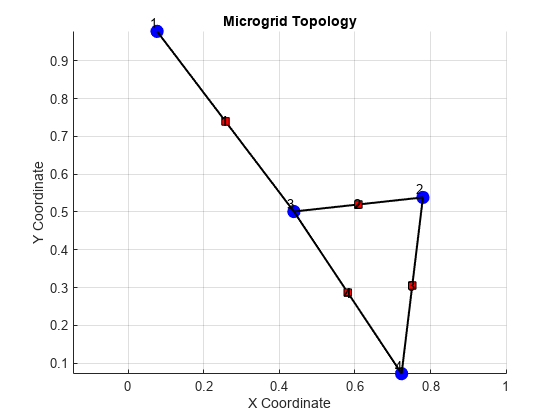

Coordinates of DGs:
    0.0763    0.9780
    0.7799    0.5385
    0.4384    0.5011
    0.7235    0.0721

Adjacency Matrix:
     0     0     1     0
     0     0     1     1
     1     1     0     1
     0     1     1     0

B_il Matrix:
     1     0     0     0
     0     1     1     0
    -1    -1     0     1
     0     0    -1    -1



You have NaNs in model (<a href="yalmip.github.io/naninmodel">learn to debug</a>)


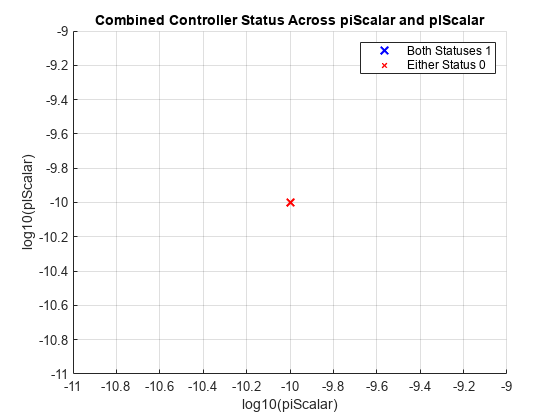

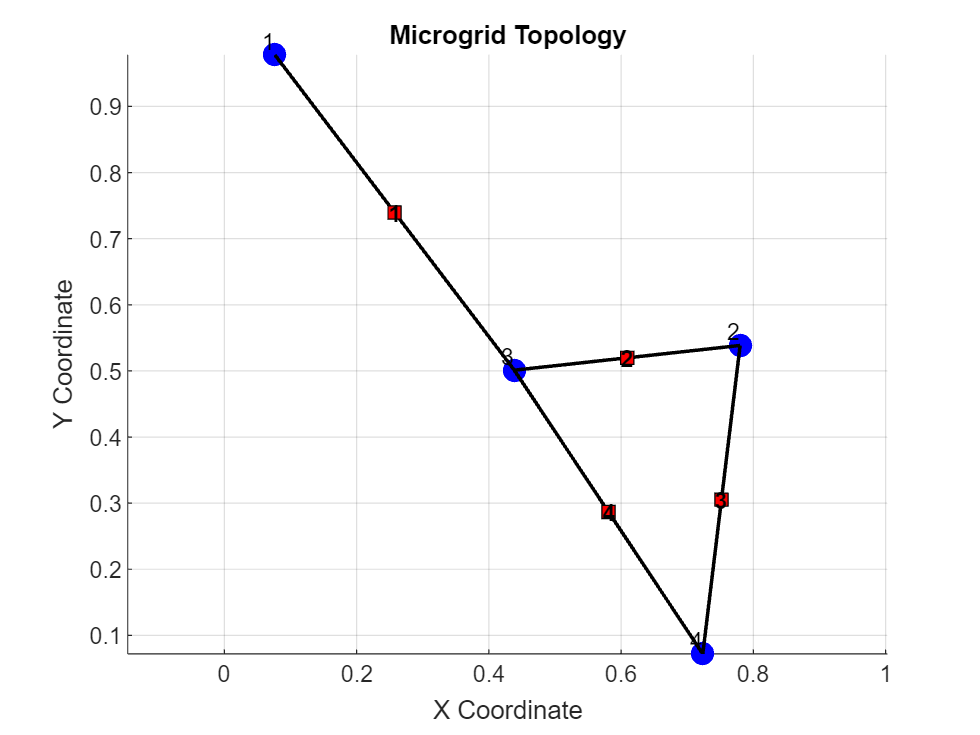

C0Array = logspace(log10(220), log10(0.022), N);  % N is the number of steps you want

for C0 = C0Array
    count = count + 1
    
    rng(7)
    
    numOfDGs = 4;
    threshold = 0.6;
    [coords, A_ij, B_il] = generateMicrogridTopology(numOfDGs, threshold);
    
    
    % Initial parameter values for DGs
    R0 = 0.02;      % Resistance
    L0 = 0.01;      % Inductance
    % C0 = 22;    % Capacitance
    RL0 = 0.3;      % Load Resistance
    Y0 = 1/RL0;     % Load Conductance
    IL0 = 5;        % Constant Current Load
    LoadNoiseMean = 10;
    LoadNoiseStd = 2;
    
    
    for i = 1:1:numOfDGs
        DG{i} = GenerateDG(R0,L0,C0,RL0,IL0,coords(i,:));
        
        [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i});
    end
    
    % Initial parameter values for Lines
    Rl0 = 2;     % Line Resistance
    Ll0 = 0.01;     % Line Inductance
    
    numOfLines = size(B_il,2);
    
    for l = 1:1:numOfLines
        Line{l} = GenerateLine(Rl0,Ll0);
        [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l});
    end
    BarGamma = 1000000;    % Fixed value for gammaBar
    isSoft = 1;      % Set to 1 to avoid the hard graph constraint
    
    plotCombinedControlDesign(DG, Line, B_il, BarGamma, A_ij, isSoft, numOfDGs, numOfLines);
    print(['Results/CResults/C0_',num2str(count)], '-dpng', '-r600')
end